radius = 500;

theta = linspace(0, 2*pi, 1000);

x = radius * cos(theta);
y = radius * sin(theta);

point1 = [-1000, 0];
point2 = [3500, 0];

planeB_point = zeros(93, 2);

planeB_point(1,:) = [-1000, 0];
delta = [750*50/866, -433*50/866];
for i=1:16
    planeB_point(i+1,:) = planeB_point(1,:)+delta*i;
end

theta = atan2(-443, -250);
thetas = linspace(theta, -1.4846, 7);
for i=1:7 
    planeB_point(i+17,:) = 500*[cos(thetas(i)), sin(thetas(i))];
end

tangentPoints = findTangentPoints(0, 0, 500, 3500, 0);
planeB_point(25:93,1) = linspace(71.4286, 3500, 69);
planeB_point(25:93,2) = linspace(-494.8717, 0, 69);

planeA_point = zeros(93,2);

theta_1 = linspace(pi, 0, 27);

planeA_point(1,:) = [-1000, 0];
for i=1:27
    planeA_point(i+1,:) = planeA_point(i,:) + 50*[cos(theta_1(i)), sin(theta_1(i))];
end

tangent = findTangentPoints(0, 0, 500, planeA_point(i+1,1), planeA_point(i+1,2))

tangent =   145.4304  478.3827
 -442.4722 -232.8484


d = sqrt((tangent(1,1)-planeA_point(i+1,1))^2+(tangent(1,2)-planeA_point(i+1,2))^2)

d = 1.1972e+03

num = round(d/50)

num = 24

planeA_point(i+1:i+num, :) = [linspace(planeA_point(i+1,1), tangent(1,1), num)',linspace(planeA_point(i+1,2), tangent(1,2), num)'];

start_theta = atan((tangent(1,1)-planeA_point(i+1,1))/(planeA_point(i+1,2)-tangent(1,2)))

start_theta = 1.2757

num_2 = round(start_theta/0.1);
theta_3 = linspace(start_theta, 0, num_2);
for j=1:num_2
    planeA_point(i-1+num+j,:) = 500*[cos(theta_3(j)), sin(theta_3(j))];
end
i+num+j

ans = 64

d_2 = sqrt((planeA_point(61,1)-3500)^2 + planeA_point(61,2)^2);
num_3 = round(d_2/50)

num_3 = 60

planeA_point(61:60+num_3,:) = [linspace(planeA_point(60,1), 3500, num_3)', linspace(planeA_point(60,2), 0, num_3)'];

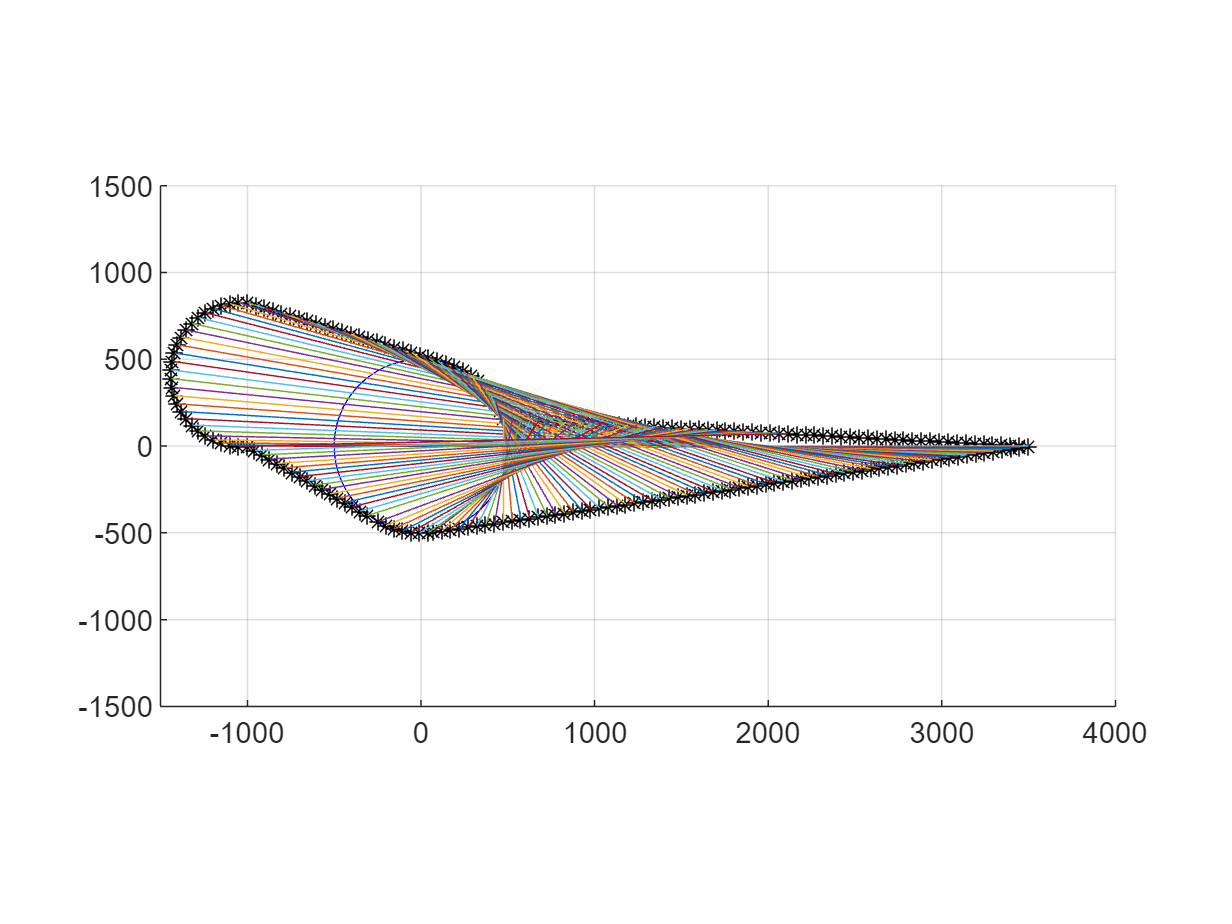

clf
figure;
hold on;

plot(x, y, 'b');

plot(point1(1), point1(2), '*k');
plot(point2(1), point2(2), '*k');

axis equal;

xlim([-1500 4000]);
ylim([-1500 1500]);

grid on;

plot(planeB_point(:,1), planeB_point(:,2), '*k');
plot(planeA_point(:,1), planeA_point(:,2), '*k');
for i=1:93
    plot([planeA_point(i,1),planeB_point(94-i,1)], [planeA_point(i,2), planeB_point(94-i,2)])
end
hold on;